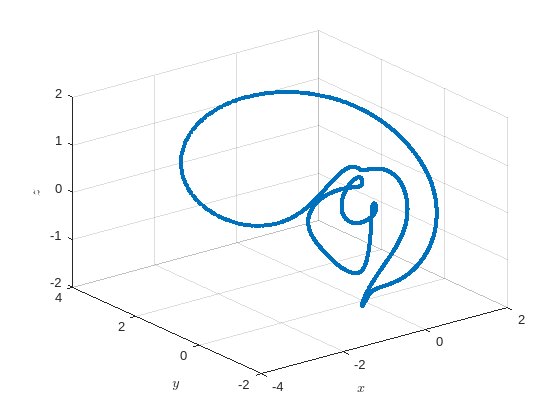

% Loading and analyze the data from homotopy solver
A = load("nash_state_dataXX.csv");
H1 = load("nash_payoff_h1XX.csv");
H2 = load("nash_payoff_h2XX.csv");

B = zeros(size(A));
B(:, end) = [];

for i = 1:size(B, 2)
    B(:, i) = A(:, i+1)./(1+A(:, 1));
end
% eliminate some data to showcase the linking
el1 = [0.56238, 0.193236, 0.263866];
el2 = [0.610453, 0.085457, -1.17257];
for i = 1:size(B, 1)
    if norm(B(i, :)-el1) < 0.1
        B(i, :) = [0 0 0];
    elseif norm(B(i, :)-el2) < 0.1
        B(i, :) = [0 0 0];
    end
end
B(all(B==0, 2), :) = [];

figure()
scatter3(B(:, 1), B(:, 2), B(:, 3), '.')
xlabel('$x$', Interpreter='latex');
ylabel('$y$', Interpreter='latex');
zlabel('$z$', Interpreter='latex');

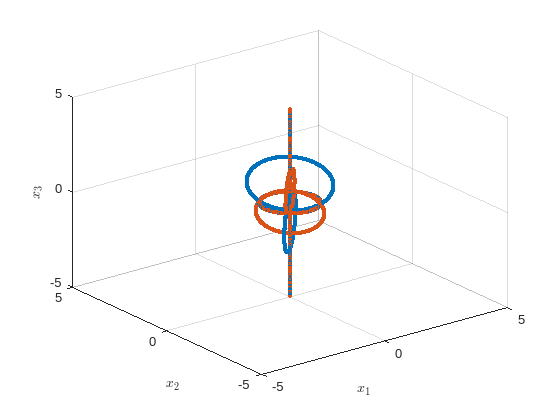

A = load("nash_state_data.csv");
H1 = load("nash_payoff_h1.csv");
H2 = load("nash_payoff_h2.csv");
B = zeros(size(A));
B(:, end) = [];

for i = 1:size(B, 2)
    B(:, i) = A(:, i+1)./(1+A(:, 1));
end
for i = 1:size(B, 1)
    if norm(B(i, :)-el1) < 0.1
        B(i, :) = [0 0 0];
    elseif norm(B(i, :)-el2) < 0.1
        B(i, :) = [0 0 0];
    end
end
B(all(B==0, 2), :) = [];

figure()
scatter3(B(:, 1), B(:, 2), B(:, 3), '.')
xlabel('$x_1$', Interpreter='latex');
ylabel('$x_2$', Interpreter='latex');
zlabel('$x_3$', Interpreter='latex');
hold on
A = load("nash_state_dataQPD.csv");
H1 = load("nash_payoff_h1QPD.csv");
H2 = load("nash_payoff_h2QPD.csv");

B = zeros(size(A));
B(:, end) = [];

for i = 1:size(B, 2)
    B(:, i) = A(:, i+1)./(1+A(:, 1));
end

scatter3(B(:, 1), B(:, 2), B(:, 3), '.')
xlabel('$x_1$', Interpreter='latex');
ylabel('$x_2$', Interpreter='latex');
zlabel('$x_3$', Interpreter='latex');
xlim([-5,5])
ylim([-5,5])
zlim([-5,5])

## Use stereographic projection

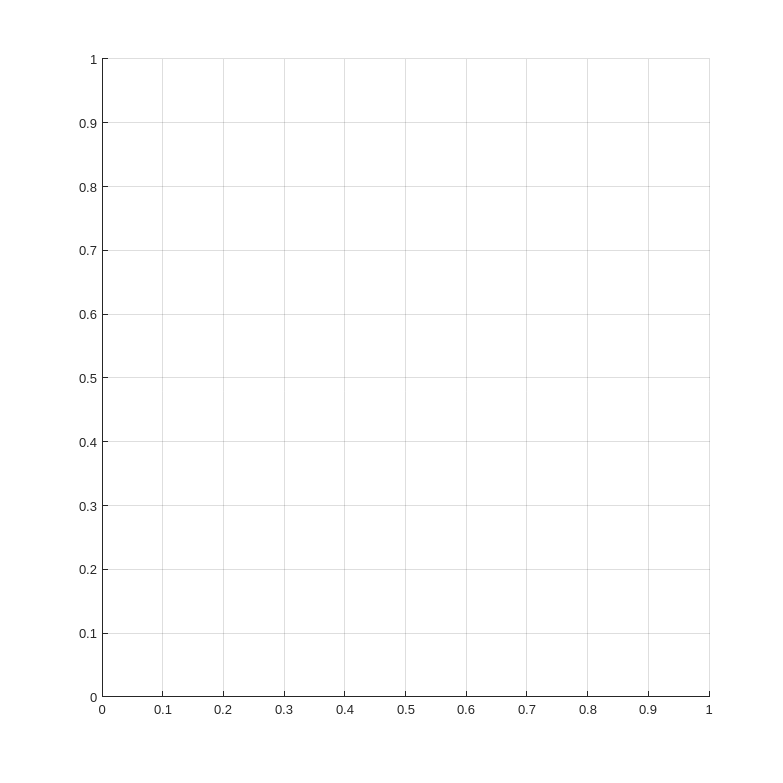


% Loading and analyze the data from homotopy solver
A = load("nash_state_dataQPD.csv");
H1 = load("nash_payoff_h1QPD.csv");
H2 = load("nash_payoff_h2QPD.csv");

B = zeros(size(A));
B(:, end) = [];

for i = 1:size(B, 2)
    B(:, i) = A(:, i+1)./(1+A(:, 1));
end
figure("Position",[200, 200, 1200, 1200])
hold on
grid on


scatter3(Bsat(:, 1), Bsat(:, 2), Bsat(:, 3), 'filled', 'o', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b')

Index in position 2 exceeds array bounds.

scatter3(Bunsat(:, 1), Bunsat(:, 2), Bunsat(:, 3), 'r.')
xlabel('$x_1$', Interpreter='latex');
ylabel('$x_2$', Interpreter='latex');
zlabel('$x_3$', Interpreter='latex');
% title('Nash variety for Quantum Prisoners dilemma')
zlim([-3,3])
ylim([-3,3])
xlim([-3,3])
xr = 3; yr = 3;
xx = [-xr, xr, xr, -xr];
yy = [-yr, -yr, yr, yr];
zz = [0 0 0 0];
fill3(xx, yy, zz, 'c', 'FaceAlpha', 0.3)

## another visualization: the hyperoctant picture

% Take the datapoints and fold onto the first hyperoctant
C = abs(A);

% Implement the SO(n) element that transforms the first hyperquadrant to
% be such that the gnominic projection looks like a regular n-simplex.
n = 4; % for S3, the ambiebt space for natural embedding is R4
r = sqrt(1 - (1/n));


The image of maximally entangled states and separable states in S3

k = 0

k = 0

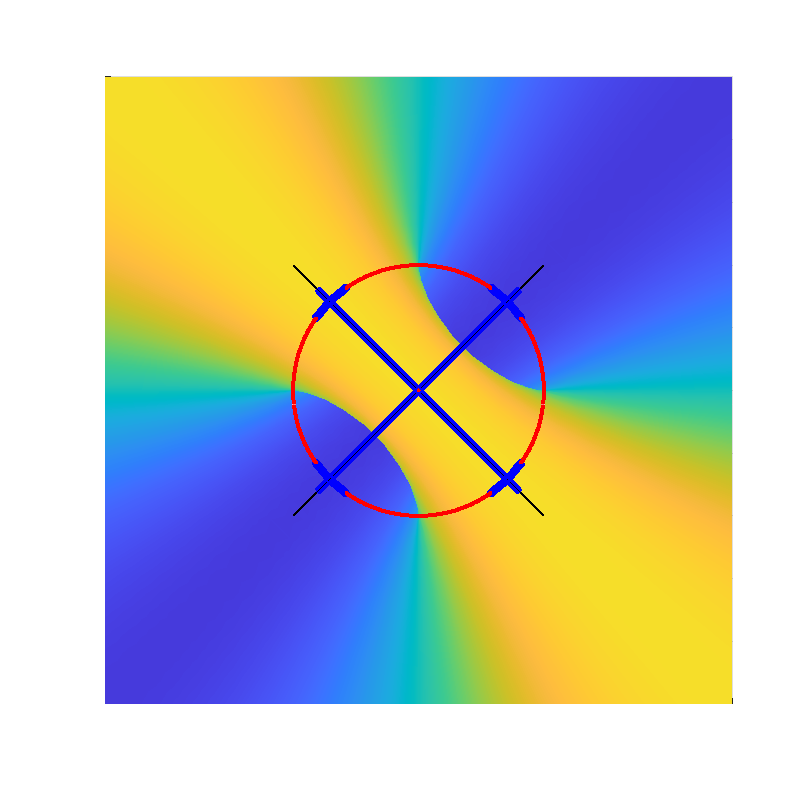

% Define the equation of the surface
surfaceEq = @(x, y, z) (1 - (x.^2 + y.^2 + z.^2)) .* z - 2 .* x .* y - k * (1+(x.^2+y.^2+z.^2)).^2;
surfaceEq1 = @(x, y, z) (1 - (x.^2 + y.^2 + z.^2)) .* z - 2 .* x .* y + k * (1+(x.^2+y.^2+z.^2)).^2;
% Plot the surface using fimplicit3
figure("Position", [200, 200, 1200, 1200])
hold on
xr = 5;
yr = 5;
zr = 5;
falpha = 1;
fimplicit3(surfaceEq, [-xr, xr, -yr, yr, -zr, zr], 'EdgeColor', 'none', 'FaceAlpha', falpha)
fimplicit3(surfaceEq1, [-xr, xr, -yr, yr, -zr, zr], 'EdgeColor', 'none', 'FaceAlpha', falpha)
xlabel('x')
ylabel('y')
zlabel('z')
title('Intermediate entanglement')
grid on
axis equal

a = linspace(0,2*pi,100);
r = sqrt(2);
x1 = r*cos(a)/sqrt(2);
y1 = -r*cos(a)/sqrt(2);
z1 = r*sin(a)-1;
plot3(x1, y1, z1, 'LineWidth', 2, 'Color', 'k');
x2 = r*cos(a)/sqrt(2);
y2 = r*cos(a)/sqrt(2);
z2 = r*sin(a)+1;
plot3(x2, y2, z2, 'LineWidth', 2, 'Color', 'k');
xlabel('x');
ylabel('y');
zlabel('z');
scatter3(Bsat(:, 1), Bsat(:, 2), Bsat(:, 3), 'filled', 'o', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b')
scatter3(Bunsat(:, 1), Bunsat(:, 2), Bunsat(:, 3), 'r.')
xlim([-5,5]/2)
ylim([-5,5]/2)
zlim([-5,5]/2)







figure()
% Define the implicit function in terms of y and z
implicitFunction = @(y, z) 1 - 2*y.^2 - z.^2 - 2*z;

% Create a range for y
y = linspace(-1, 1, 500);

% Solve for z for each y
z = zeros(size(y));
for i = 1:length(y)
    z(i) = fzero(@(z) implicitFunction(y(i), z), 0); % Using fzero to find root for each y
end

Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -1.7162e+154 is -Inf.)
Check function or try again with a different starting value.
Exiting fzero: aborting search for an interval containing a sign change
    because NaN or Inf function value encountered during search.
(Function value at -1.7162e+154 is -Inf.)
Check function or try again with a different starting value.



% x = -y
x = -y;

% Plot the curve
% plot3(x, y, z, 'LineWidth', 2);
% xlabel('x');
% ylabel('y');
% zlabel('z');
% title('Solution to the equations $1 - x^2 - y^2 - z^2 = 2z$ and $x = -y$');
% grid on;
% axis equal;


a = linspace(0,2*pi,100);
r = sqrt(2);
figure()
hold on
x1 = r*cos(a)/sqrt(2);
y1 = -r*cos(a)/sqrt(2);
z1 = r*sin(a)-1;
plot3(x1, y1, z1, 'LineWidth', 2, 'Color', 'r');
x2 = r*cos(a)/sqrt(2);
y2 = r*cos(a)/sqrt(2);
z2 = r*sin(a)+1;
plot3(x2, y2, z2, 'LineWidth', 2, 'Color', 'r');
surfaceEq = @(x, y, z) (1 - (x.^2 + y.^2 + z.^2)) .* z - 2 .* x .* y

surfaceEq = function_handle with value:
    @(x,y,z)(1-(x.^2+y.^2+z.^2)).*z-2.*x.*y


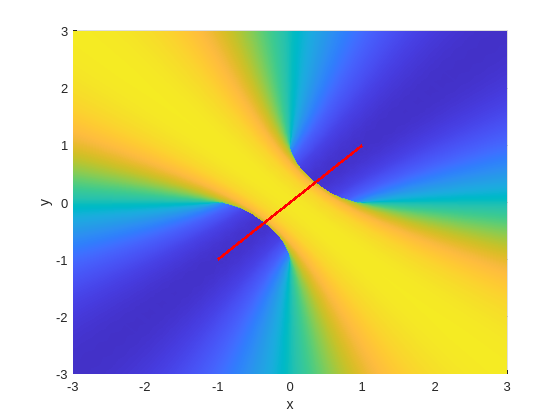

xr = 3;
yr = 3;
zr = 3;
falpha = 1;
fimplicit3(surfaceEq, [-xr, xr, -yr, yr, -zr, zr], 'EdgeColor', 'none', 'FaceAlpha', falpha)
xlabel('x');
ylabel('y');
zlabel('z');
zlim([-3,3])
ylim([-3,3])
xlim([-3,3])
grid on

inverseStereo(0,0,1)

ans =      0     0     0     1


Expressing the intermediately entangled states as a surface in S3?

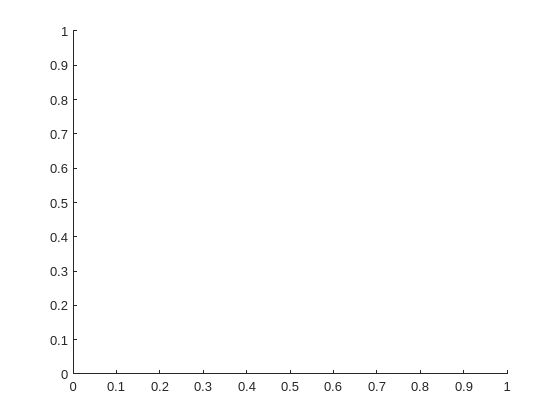

figure()
hold on

NEcons1 = @(x,y,z) (1-x.^2-y.^2-z.^2).^2 + 2*x.^2 - 4*y.^2 - 2*z.^2;
NEcons2 = @(x,y,z) NEcons1(y, x, z);
Bsat = []; Bunsat = [];
for i = 1:size(B, 1)
    if NEcons1(B(i, 1), B(i, 2), B(i, 3)) < 0 && NEcons2(B(i, 1), B(i, 2), B(i, 3)) < 0
        Bsat = [Bsat; B(i, :)];
    else
        Bunsat = [Bunsat; B(i, :)];
    end
end

Unrecognized function or variable 'B'.

scatter3(Bsat(:, 1), Bsat(:, 2), Bsat(:, 3), 'filled', 'o')
scatter3(Bunsat(:, 1), Bunsat(:, 2), Bunsat(:, 3), '.')

xr = 3;
yr = 3;
zr = 3;
falpha = 1;
fimplicit3(NEcons1, [-xr, xr, -yr, yr, -zr, zr], 'EdgeColor', 'none', 'FaceAlpha', falpha)
xlim([-xr,xr])
ylim([-yr,yr])
zlim([-zr,zr])
grid on

AA = [1 2 3; 4 5 6; 7 8 9];
sum(AA, 2)

ans =      6
    15
    24


function X = inverseStereo(x1,x2,x3)
X = zeros(1, 4);
r2 = x1^2+x2^2+x3^2;
X(1) = (1-r2)/(1+r2);
X(2) = 2*x1/(1+r2);
X(3) = 2*x2/(1+r2);
X(4) = 2*x3/(1+r2);
end


